# Wykresy powierzchniowe

[Wykesy powierzchniowe](https://www.mathworks.com/help/matlab/ref/surf.html) stosuje się w celu wizualizacji powierzchni matematycznych.

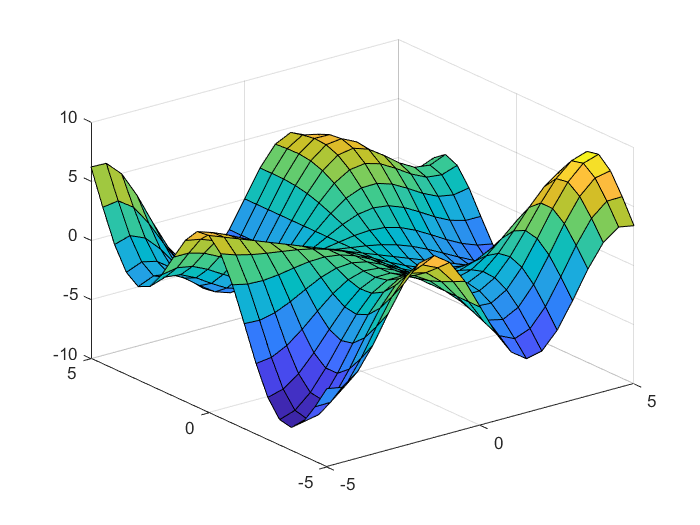

x = [-5:0.5:5];
y = [-5:0.5:5];
[X,Y] = meshgrid(x,y);
Z = Y.*sin(X) - X.*cos(Y);
surf(X,Y,Z)

Możliwe jest dostosowanie wykresu powierzchni do konkretnych wymagań poprzez użycie opcji. Tu usunięto linie siatki oraz dodano przezroczystośc do powierzchni.

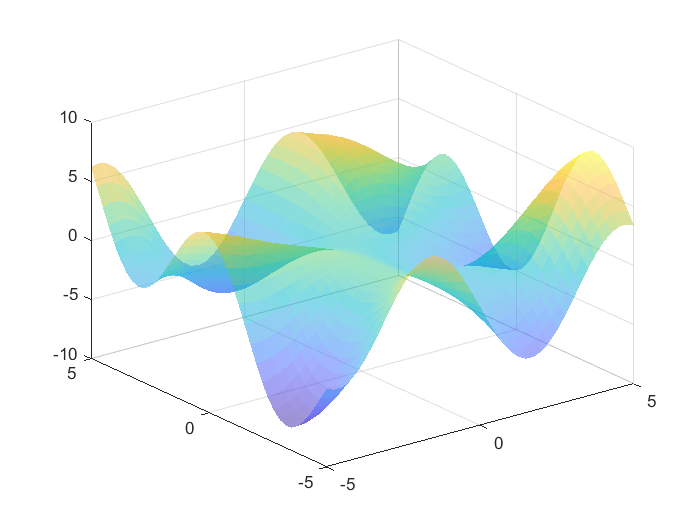

x = [-5:0.25:5];
y = [-5:0.25:5];
[X,Y] = meshgrid(x,y);
Z = Y.*sin(X) - X.*cos(Y);
surf(X,Y,Z,'FaceAlpha',0.5,"EdgeColor","none")

Możliwe jest użycie kolorowania wykresu innego od domyślnego. Np. poniżej usunięto kolor.

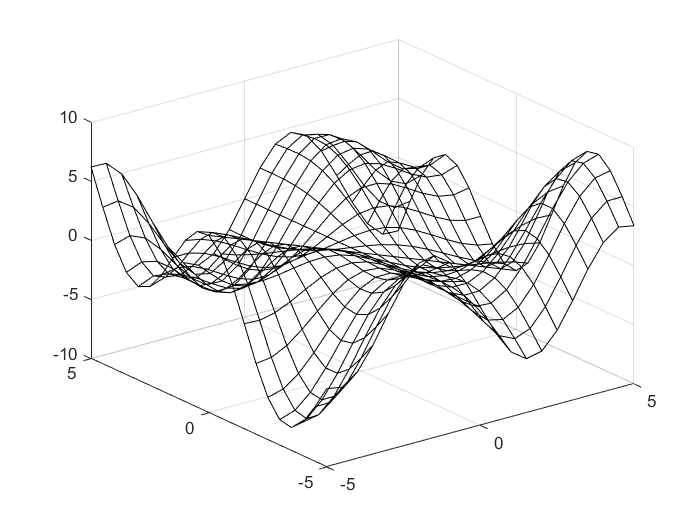

x = [-5:0.5:5];
y = [-5:0.5:5];
[X,Y] = meshgrid(x,y);
Z = Y.*sin(X) - X.*cos(Y);
surf(X,Y,Z,"FaceColor","none")

W poniższym przykładzie jako zmiennej defniującejkolor użyto wielkości gradientu funkcji.

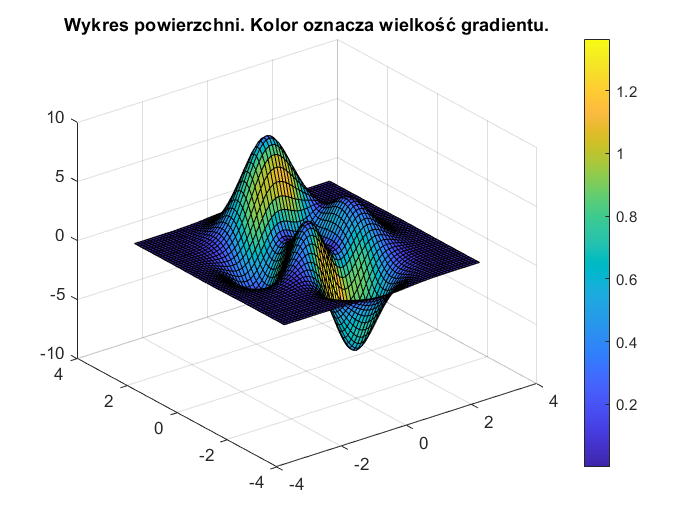

[x,y] = meshgrid(-3:0.1:3);
z = 3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2);

[u,v] = gradient(z);
c = sqrt(u.^2 + v.^2);
surf(x,y,z,c)
colorbar()
title("Wykres powierzchni. Kolor oznacza wielkość gradientu.")